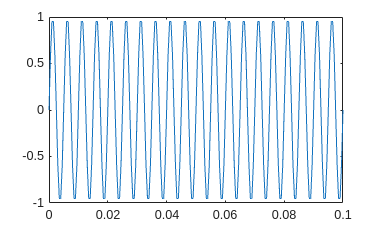


f1=200; %Hz
t=0:1/(10*f1):0.1;
X=sin(2*pi*f1*t);
plot(t,X)

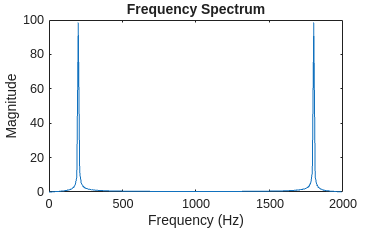


freqx=fft(X);
freqx = abs(freqx); % Compute the magnitude of the FFT
f = (0:length(freqx)-1)* (1/(t(2)-t(1))) / length(freqx); % Frequency vector
plot(f, freqx); % Plot the frequency spectrum
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum');

Now add the noise 

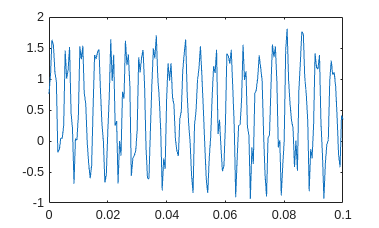


noise=rand(1,length(t));
Y=X+noise; 
plot(t,Y)

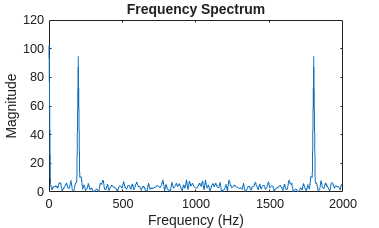


freqx=fft(Y);
freqx = abs(freqx); % Compute the magnitude of the FFT
f = (0:length(freqx)-1)* (1/(t(2)-t(1))) / length(freqx); % Frequency vector
plot(f, freqx); % Plot the frequency spectrum
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum');

Now add a low pass filter using the filter coefficients

% Apply a low-pass filter to the noisy signal
fc = 250; % Cut-off frequency
[b, a] = butter(2, fc/(1/(2*(t(2)-t(1)))), 'low'); % 6th order Butterworth filter
Y_filtered = filter(b, a, Y); 


Again provide the plot after passing it througha low pass filter

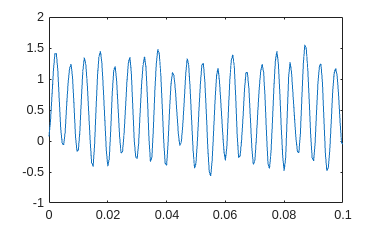

plot(t,Y_filtered )

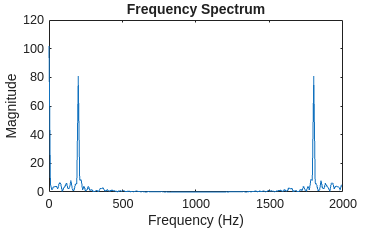


freqx=fft(Y_filtered);
freqx = abs(freqx); % Compute the magnitude of the FFT
f = (0:length(freqx)-1)* (1/(t(2)-t(1))) / length(freqx); % Frequency vector
plot(f, freqx); % Plot the frequency spectrum
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum');

applying butterworth filter manually 

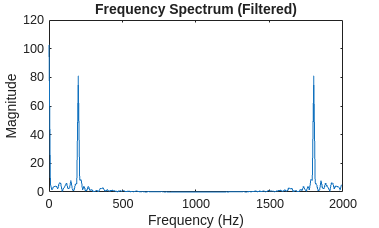

b = [0.0976 0.1953 0.0976];
a = [1 -0.9458 0.3330];

% ----- Explicit IIR filtering (NO filter() ) -----
N = length(Y);
Y_lowpass = zeros(1,N);

for n = 1:N
    x0 = Y(n);
    x1 = 0; x2 = 0;
    y1 = 0; y2 = 0;

    if n-1 >= 1
        x1 = Y(n-1);
        y1 = Y_lowpass(n-1);
    end
    if n-2 >= 1
        x2 = Y(n-2);
        y2 = Y_lowpass(n-2);
    end

    % y[n] = b0*x[n] + b1*x[n-1] + b2*x[n-2] - a1*y[n-1] - a2*y[n-2]
    Y_lowpass(n) = b(1)*x0 + b(2)*x1 + b(3)*x2 ...
                   - a(2)*y1 - a(3)*y2;
end

% ----- Frequency spectrum of filtered signal -----
fs = 1/(t(2)-t(1));
F = (0:N-1)*(fs/N);

spec = abs(fft(Y_lowpass));
plot(F, spec);
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Frequency Spectrum (Filtered)');

% xlim([0 fs/2]);